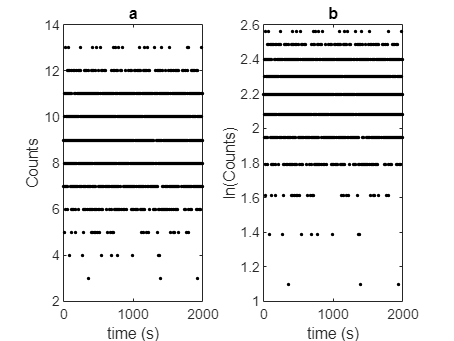

n0cs = 0; % Initial number of 137Cs nuclei
n0ba = 0; % 5e14*lambda_p/lambda_d % Initial number of 137mBa nuclei
run('PVB303_Prac2_Sec_Equilibrium_sim.m')

figure
subplot(1,2, 1)
plot(times, detector, 'k.')
title('a')
xlabel('time (s)')
ylabel('Counts')

subplot(1,2, 2)
plot(times, logdet, 'k.')
title('b')
xlabel('time (s)')
ylabel('ln(Counts)')

noiseyData = detector;
fprintf('mean = %0.4f, stdev = %0.4f', mean(noiseyData),std(noiseyData))

mean = 9.0320, stdev = 1.6442

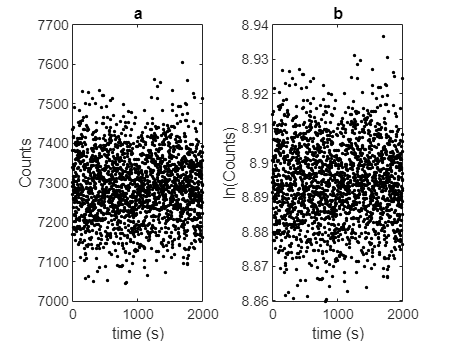

n0cs = 5e14;
n0ba = 5e14*lambda_p/lambda_d; 
run('PVB303_Prac2_Sec_Equilibrium_sim.m')

figure
subplot(1,2, 1)
plot(times, detector, 'k.')
title('a')
xlabel('time (s)')
ylabel('Counts')

subplot(1,2, 2)
plot(times, logdet, 'k.')
title('b')
xlabel('time (s)')
ylabel('ln(Counts)')

equilData = detector;
fprintf('mean = %0.4f, stdev = %0.4f', mean(equilData),std(equilData))

mean = 7290.8825, stdev = 86.2177

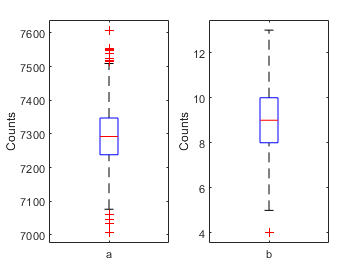

% Boxplots
figure
subplot(1,2,1)
boxplot(equilData)
ylabel('Counts')
xticklabels('a')

subplot(1,2,2)
boxplot(noiseyData)
ylabel('Counts')
xticklabels('b')

n0cs = 0; 
n0ba = 5e14*lambda_p/lambda_d; 
run('PVB303_Prac2_Sec_Equilibrium_sim.m')
X = times;
Y = logdet;

[slope1, intercept1, slopeStdErr1, interceptStdErr1] = linearRegression(X(1:500),Y(1:500))

slope1 = -0.0045

intercept1 = 8.8946

slopeStdErr1 = 7.2867e-06

interceptStdErr1 = 6.5272e-07

f1 = @(q) slope1*q + intercept1

f1 = function_handle with value:
    @(q)slope1*q+intercept1


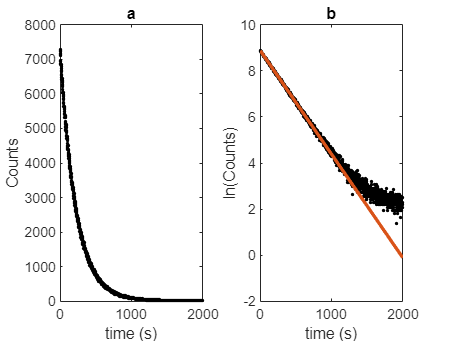

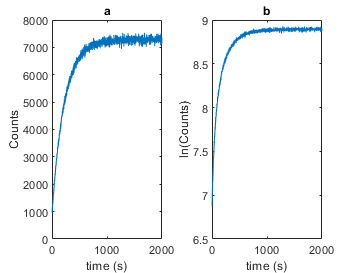


figure
subplot(1,2, 1)
plot(X, detector, 'k.')
title('a')
xlabel('time (s)')
ylabel('Counts')

subplot(1,2, 2)
plot(X, Y, 'k.')
hold on
fplot(f1, [times(1), times(end)], 'LineWidth', 2)
title('b')
xlabel('time (s)')
ylabel('ln(Counts)')

n0cs = 5e14; 
n0ba = 1e7; 
run('PVB303_Prac2_Sec_Equilibrium_sim.m')

Csec = mean(detector(1100:end));
x = detector(1)/Csec;

X = times;
Y = log(abs((detector-Csec)/Csec * 1/(x-1)));

[slope2, intercept2, slopeStdErr2, interceptStdErr2] = linearRegression(X(1:500),Y(1:500))

slope2 = -0.0045

intercept2 = -8.4789e-04

slopeStdErr2 = 1.7233e-05

interceptStdErr2 = 1.5436e-06

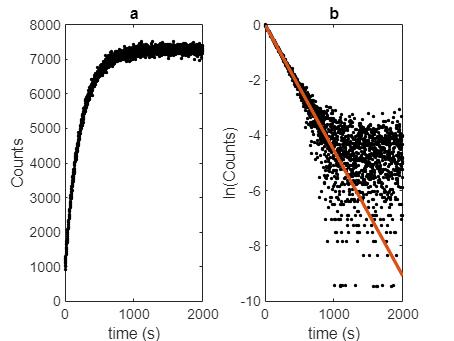

f2 = @(q) slope2*q + intercept2;

figure
subplot(1,2, 1)
plot(times, detector, 'k.')
title('a')
xlabel('time (s)')
ylabel('Counts')

subplot(1,2, 2)
plot(X, Y, 'k.')
hold on 
fplot(f2, [times(1), times(end)], 'LineWidth', 2)
title('b')
xlabel('time (s)')
ylabel('ln(Counts)')